# ME5554/AOE5754/ECE5754 Applied Linear Systems

# Homework 3

Md Riasat Morshed Khan    

09/23/2024

## Problem 1

An **Idempotent **matrix has the property that when it is multiplied by itself, the result is the original matrix, i.e. $\textrm{AA}=\mathbf{A}$.  The matrix $\mathbf{A}=\left\lbrack \begin{array}{cc}
3 & -3\\
a & -2
\end{array}\right\rbrack$ will be Idempotent for a particular value of the unknown element $a$.  First determine the value of $a$ which causes the matrix to be Idempotent, then, substitute the numerical value of $a$ in the matrix and determine the eigenvalues and the corresponding eigenvectors without using the EIG function.  Check your answers with the EIG function.

%Q(1)
syms a x;
A = [3 -3;a -2];
mult = A*A;
a_valEqn = mult(1,1) == A(1,1);
a_val = solve(a_valEqn,a);

A_num = subs(A,a,a_val);
%Q(1) Eigen Value Part
lambda = diag([x x]);
det_A = det(A_num-lambda);
eigVal = solve(det_A == 0,x);
eigVal_num = double(eigVal);
fprintf('a value is %d',a_val);

a value is 2

fprintf('The eigen values are:\n %d\n %d',eigVal_num)

The eigen values are:
 0
 1

Now, the given A matrix is $\mathbf{A}=\left\lbrack \begin{array}{cc}
3 & -3\\
2 & -2
\end{array}\right\rbrack$

We know that, the eigen value equation is: $\mathit{\mathbf{A}}\lambda =\mathrm{Av}$


$$\begin{array}{l}
\Rightarrow \left\lbrack \begin{array}{cc}
3 & -3\\
2 & -2
\end{array}\right\rbrack \times 0=\left\lbrack \begin{array}{cc}
3 & -3\\
2 & -2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_{11} \\
v_{12} 
\end{array}\right\rbrack \\
\Rightarrow \left\lbrack \begin{array}{cc}
3 & -3\\
2 & -2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_{11} \\
v_{12} 
\end{array}\right\rbrack =0\\
\Rightarrow 3v_{11} -3v_{12} =0\\
\Rightarrow 2v_{11} -2v_{12} =0\\
{\Rightarrow v}_{11} =v_{12} \\
\Rightarrow \mathit{\mathbf{v}}=\left\lbrack \begin{array}{c}
v_{11} \\
v_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack 
\end{array}$$


Now, for $\lambda =1$:


$$\begin{array}{l}
\left(A-\lambda I\right)v=0\\
\Rightarrow \left(\left\lbrack \begin{array}{cc}
3 & -3\\
2 & -2
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
v_{11} \\
v_{12} 
\end{array}\right\rbrack =0\\
\Rightarrow \left\lbrack \begin{array}{cc}
2 & -3\\
2 & -3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_{11} \\
v_{!2} 
\end{array}\right\rbrack =0\\
\Rightarrow 2v_{11\;} -3v_{12} =0\\
\Rightarrow v_{11} =\frac{3}{2}v_{12} \\
\Rightarrow \mathit{\mathbf{v}}=\left\lbrack \begin{array}{c}
v_{11} \\
v_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{3}{2}\\
1
\end{array}\right\rbrack 
\end{array}$$


## Problem 2

In the textbook, $x$ generally refers to "states", $y$ generally refers to "outputs", and $u$ generally refers to "inputs".

For problem NE1.2 in the textbook, derive the state equations for all four parts.  Do NOT use the Symbolic toolbox!

a)  $\dot{y} +2y=u$


$$\begin{array}{l}
\mathrm{let},x_1 =y\\
\left\lbrack \begin{array}{c}
\dot{x_1 } 
\end{array}\right\rbrack =-2\left\lbrack x\right\rbrack +\left\lbrack 1\right\rbrack u\;\;
\end{array}$$


b)  $\ddot{y} +3\dot{y} +10y=u$


$$\begin{array}{l}
\mathrm{let},x_1 =y\\
{\;\;\;\;\;\;\;x}_2 =\dot{\;y} 
\end{array}$$


therefore, the given equation is $\begin{array}{l}
\dot{\;\dot{\;x_2 } +3x_{2\;} +10x_1 =u} \\
\dot{\dot{\;x_2 } =-10x_1 -3x_2 +u} \\
\mathrm{and}\;\dot{\;x_{1\;} =x_{2\;} } 
\end{array}$

Finally the equation takes the form of


$$\left\lbrack \begin{array}{c}
\dot{\;x_1 } \\
\dot{\;x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-10 & -3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack u$$


c)  $\ddot{\dot{y} } +2\ddot{y} +3\dot{y} +5y=u$


$$\begin{array}{l}
\mathrm{let},\;\\
x_1 =y\\
x_2 =\dot{\;y} \\
x_3 =\ddot{y} 
\end{array}$$


Substituting these equations into the main equation we obtain,


$$\begin{array}{l}
\dot{\;x_3 +x_3 +3x_2 +5x_1 =u} \\
\Rightarrow \dot{\;x_{3\;} =-5x_1 -3x_2 -x_3 +u} \\
\mathrm{and}\;\dot{\;x_1 =x_2 } \\
\mathrm{and}\;\dot{\;x_2 =x_3 } 
\end{array}$$


Rearranging the aforementioned equations into matrix form, we obtain,


$$\left\lbrack \begin{array}{c}
\dot{\;x_1 } \\
\dot{\;x_2 } \\
\dot{\;x_3 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-5 & -3 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack u$$


d)  $\begin{array}{l}
{\ddot{y} }_1 +5y_1 -10\left\lbrack y_2 -y_1 \right\rbrack =u_1 \\
{2\ddot{y} }_2 +{\dot{y} }_2 +10\left\lbrack y_2 -y_1 \right\rbrack =u_2 
\end{array}$


$$\begin{array}{l}
\mathrm{let},\\
x_1 =y_1 \\
\Rightarrow \dot{\;x_1 =\dot{\;y_1 } } \\
x_2 =\dot{\;y_2 } \\
\Rightarrow \dot{x_2 } =\ddot{y_2 } \\
x_3 =y_2 \\
\Rightarrow \dot{x_3 } =\dot{y_2 } \\
x_4 =\dot{y_2 } \\
\Rightarrow \dot{x_4 =\ddot{y_2 } } 
\end{array}$$


Now, putthing all these into the equations we obtain,


$$\begin{array}{l}
\dot{x_4 } =5x_1 -5x_3 -\frac{1}{2}x_4 +u_2 \\
\dot{\;x_2 } =-15x_1 -10x_3 +u_1 \\
\dot{\;x_{1\;} } =x_2 \\
\dot{x_3 } =x_4 
\end{array}$$


Now rearranging all these into matrix form we obtain,


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } \\
\dot{x_3 } \\
\dot{x_4 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-15 & 0 & -10 & 0\\
0 & 0 & 0 & 1\\
5 & 0 & 5 & -\frac{1}{2}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
1 & 0\\
0 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


## Problem 3

For problem NE1.2 in the textbook, derive the output equations for parts b and c assuming y is the only output.  Do NOT use the Symbolic toolbox!

b) 


$$\left\lbrack \begin{array}{c}
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


c)  


$$\left\lbrack \begin{array}{c}
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$$


## Problem 4

NE1.2 Derive the output equations for b and c assuming:  $\mathbf{y}=\left\lbrack \begin{array}{c}
\ddot{y} \\
5\dot{y} +3y
\end{array}\right\rbrack$

Do NOT use the Symbolic toolbox

b) 

From Problem 2, we can rewrite $\begin{array}{l}
\mathit{\mathbf{y}}=\left\lbrack \begin{array}{c}
\dot{\;x_2 } \\
5x_2 +3x_1 
\end{array}\right\rbrack \\
y=\left\lbrack \begin{array}{cc}
-10 & -3\\
3 & 5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack u
\end{array}$

c)  

From Problem 3, we can rewrite$\begin{array}{l}
y=\left\lbrack \begin{array}{c}
\ddot{\;y} \\
5\dot{\;y} +3y
\end{array}\right\rbrack \\
\Rightarrow y=\left\lbrack \begin{array}{c}
x_3 \\
5x_2 +3x_1 
\end{array}\right\rbrack \\
\Rightarrow y=\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
3 & 5 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack 
\end{array}$

## Problem 5

For Problem NE2.1 in the textbook, solve the ODE:  $2\dot{x} +5x=u$ for $x\left(t\right)$ given that $u\left(t\right)$ is the unit step function, and the initial state is $x\left(t_0 \right)=0$.  You may solve this problem analytically or numerically, but ultimately, you will need to generate a plot of the time response in Matlab.  Calculate an exact value for the time constant of this response.

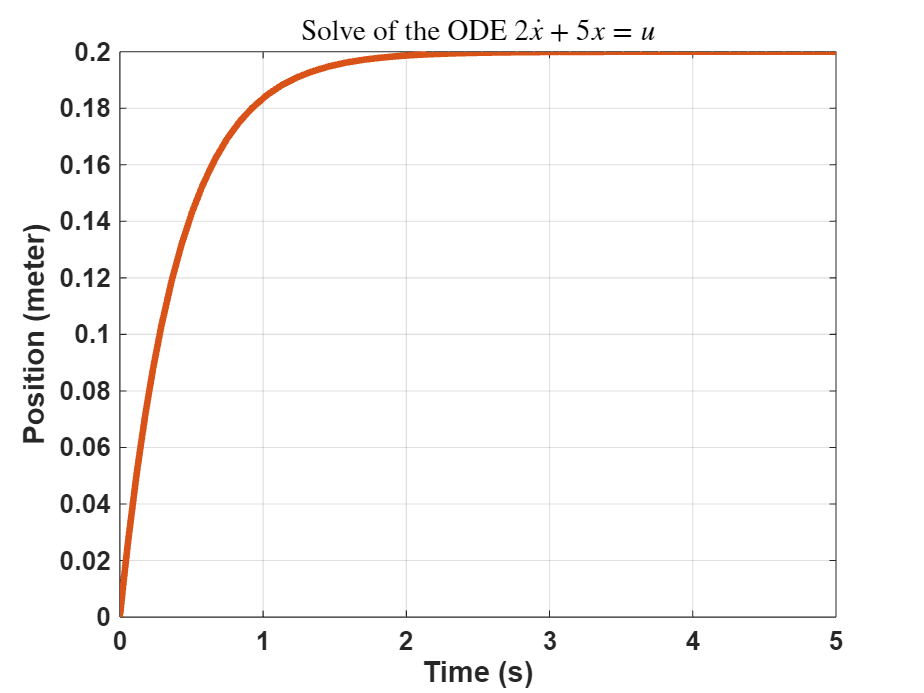

t = 1:0.01:5;
step = heaviside(t)';
[t,x] = ode45(@(t,x) -5/2*x+step/2,[0,5],zeros(1,length(t)));
plot(t,x,'LineWidth',3)
xlabel('Time (s)', 'FontSize',10,'FontWeight','bold')
ylabel('Position (meter)', 'FontSize',10,'FontWeight','bold')
title('Solve of the ODE $2\dot{x}+5x=u$','FontSize',15,'FontWeight','bold', 'Interpreter','latex')
set(gca,'FontSize',12,'FontWeight', 'bold')
grid on

## Problem 6

Example 1.2 on pages 8-9 of the textbook provides an example state-space realization for a parallel L-R-C circuit with a current input $i\left(t\right)$, and the output is the voltage $v\left(t\right)$ across the capacitor.  Example 1.5 on page 14 of the textbook provides an example state-space realization for a general 3rd order SISO dynamic system.

Assume that these two dynamic systems are now connected in series such that the output $y\left(t\right)$ from Example 1.5 is the current input $i\left(t\right)$ to Example 1.2.  Develop a **complete** state equation and output equation to describe the series-connected system.  

Hint: There can only be ONE state equation and ONE output equation!

This is not a numerical problem, and it is not easy to do using the symbolic toolbox, so you are better off just using the equation editor to derive the solution.

### Example 1.2:


$$\left\lbrack \begin{array}{c}
{\dot{x} }_1 \left(t\right)\\
{\dot{x} }_2 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & \frac{1}{L}\\
-\frac{1}{C} & -\frac{1}{R\;C}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{C}
\end{array}\right\rbrack i\left(t\right)$$



$$v\left(t\right)=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack i\left(t\right)$$


### Example 1.5:


$$\left\lbrack \begin{array}{c}
{\dot{z} }_1 \left(t\right)\\
{\dot{z} }_2 \left(t\right)\\
{\dot{z} }_3 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-a_0  & -a_1  & -a_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z_1 \left(t\right)\\
z_2 \left(t\right)\\
z_3 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
b_0 
\end{array}\right\rbrack u\left(t\right)$$



$$i\left(t\right)=\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z_1 \left(t\right)\\
z_2 \left(t\right)\\
z_3 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack u\left(t\right)$$


Let's substitute $i\left(t\right)$ in the state equation of example 1.2, 


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
{\dot{x} }_1 \left(t\right)\\
{\dot{x} }_2 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & \frac{1}{L}\\
-\frac{1}{C} & -\frac{1}{R\;C}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{C}
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z_1 \left(t\right)\\
z_2 \left(t\right)\\
z_3 \left(t\right)
\end{array}\right\rbrack \\
\begin{array}{l}
\left\lbrack \begin{array}{c}
{\dot{x} }_1 \left(t\right)\\
{\dot{x} }_2 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & \frac{1}{L}\\
-\frac{1}{C} & -\frac{1}{R\;C}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
\frac{1}{C} & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z_1 \left(t\right)\\
z_2 \left(t\right)\\
z_3 \left(t\right)
\end{array}\right\rbrack \mathrm{If}\;\mathrm{we}\;\mathrm{combine}\;\mathrm{this}\;\mathrm{equation}\;\mathrm{and}\;\mathrm{the}\;\mathrm{state}\;\mathrm{equation}\;\mathrm{from}\;\mathrm{equation}\;1\ldotp 5,\mathrm{the}\;\mathrm{combined}\;\mathrm{state}\;\mathrm{eqn}\;\mathrm{becomes}\\
\left\lbrack \begin{array}{c}
{\dot{x} }_1 \left(t\right)\\
{\dot{x} }_2 \left(t\right)\\
{\dot{z} }_1 \left(t\right)\\
{\dot{z} }_2 \left(t\right)\\
{\dot{z} }_3 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
0 & \frac{1}{L} & 0 & 0 & 0\\
-\frac{1}{C} & -\frac{1}{\mathrm{RC}} & \frac{1}{C} & 0 & 0\\
0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 1\\
0 & 0 & -a_0  & -a_1  & -a_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
z_1 \\
z_2 \\
z_3 
\end{array}\right\rbrack 
\end{array}
\end{array}$$


And the output equation will be 


$$v\left(t\right)=\left\lbrack \begin{array}{ccccc}
0 & 1 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)\\
z_3 \left(t\right)\\
z_2 \left(t\right)\\
z_3 \left(t\right)
\end{array}\right\rbrack$$
